clear all;
clc
load('brakeInput.mat')


## Given Data (brake components)

## Front Calipers (...)

## Rear Calipers (...)

## Front Master Cylinder (...)

## Rear Master Cylinder (...)

## Downforce

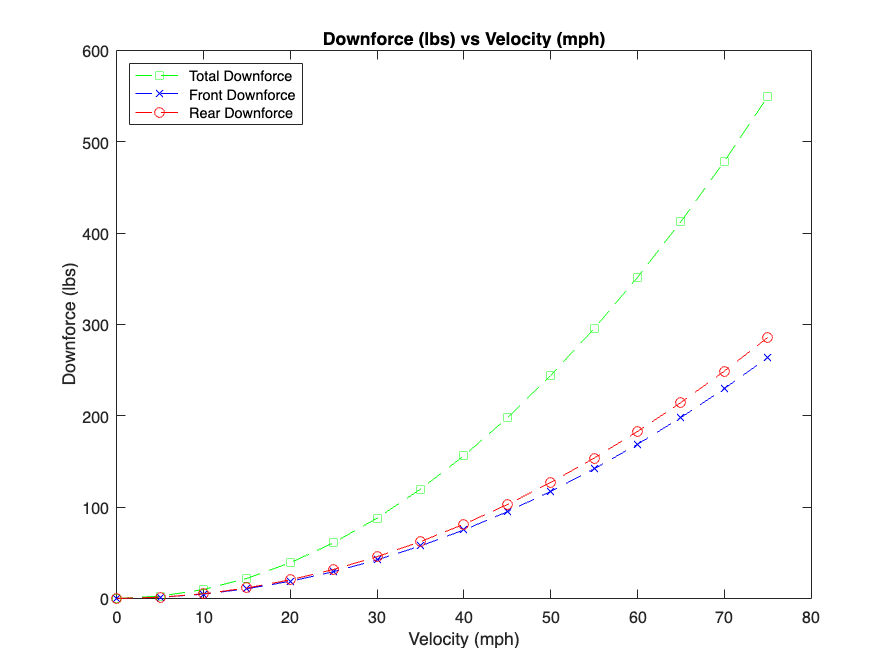

figure
plot(V, df, '--gs', V, df_front, '--bx', V, df_rear, '--ro')
xlabel('Velocity (mph)')
ylabel('Downforce (lbs)')
legend('Total Downforce', 'Front Downforce', 'Rear Downforce', 'Location','northwest')
title('Downforce (lbs) vs Velocity (mph)')

## Braking Distance

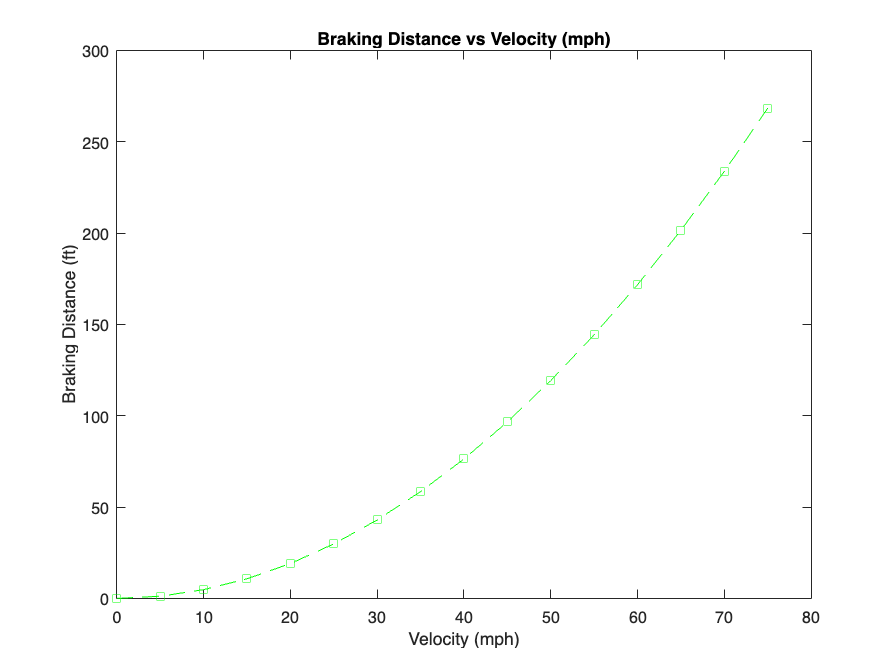

figure
plot(V, braking_dist, '--gs')
xlabel('Velocity (mph)')
ylabel('Braking Distance (ft)')
title('Braking Distance vs Velocity (mph)')

## Kinetic Energy at Specific Speed Changes

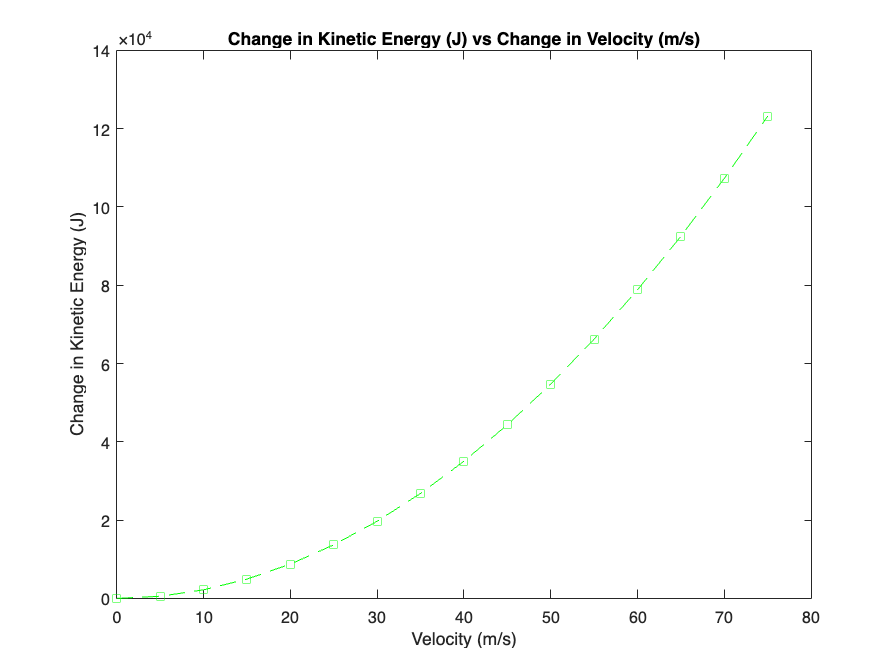

figure
plot(V, change_KE, '--gs')
xlabel('Velocity (m/s)')
ylabel('Change in Kinetic Energy (J)')
title('Change in Kinetic Energy (J) vs Change in Velocity (m/s)')

## Tractive Force

% TE = [ engine torque(overall efficiency of powertrain)(transmission ratio
% of first gear)(rear axle ratio) ] / tire radius

engine_torque = 0; %%

pow_train_eff = .95;
% efficiency with 1 axle = .95

tran_ratio = 0; %%

rear_axle_ratio = 0; %%



## Max Permissable Deceleration of Car at Different Speeds Due to Downforce

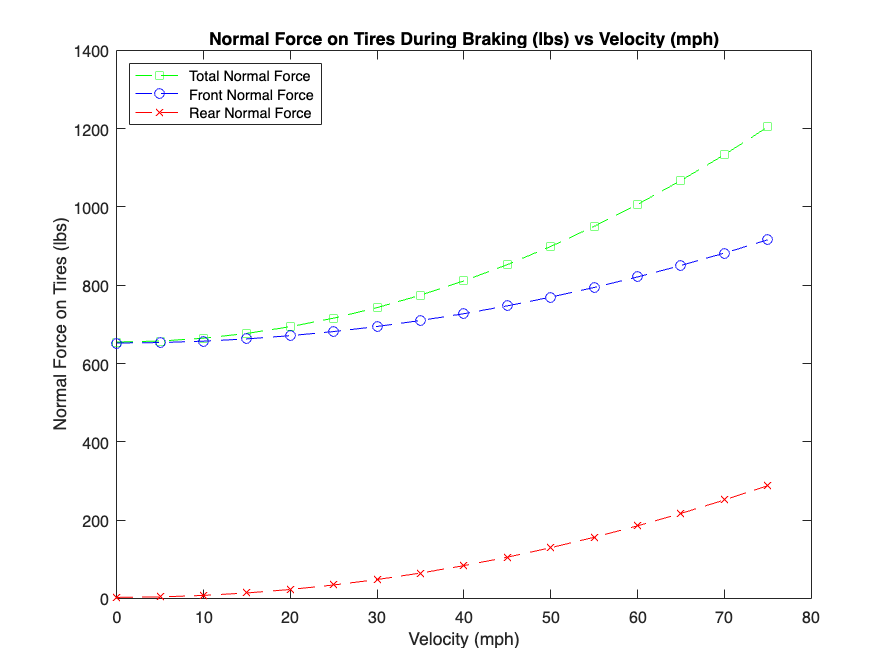

figure
plot(V, N_total, '--gs', V, N_front, '--bo', V, N_rear, '--rx')
xlabel('Velocity (mph)')
ylabel('Normal Force on Tires (lbs)')
title('Normal Force on Tires During Braking (lbs) vs Velocity (mph)')
legend('Total Normal Force', 'Front Normal Force', 'Rear Normal Force', 'Location', 'northwest')

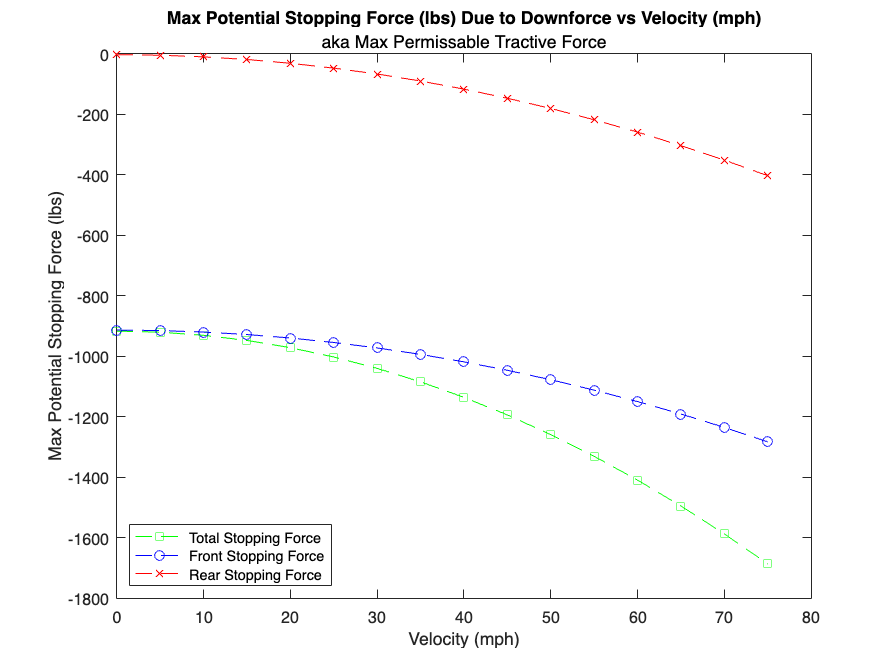

figure
plot(V, total_stopping_force, '--gs', V, front_stopping_force, '--bo', V, rear_stopping_force, '--rx')
xlabel ('Velocity (mph)')
ylabel('Max Potential Stopping Force (lbs)')
title('Max Potential Stopping Force (lbs) Due to Downforce vs Velocity (mph)', 'aka Max Permissable Tractive Force')
legend('Total Stopping Force', 'Front Stopping Force', 'Rear Stopping Force', 'Location','southwest')

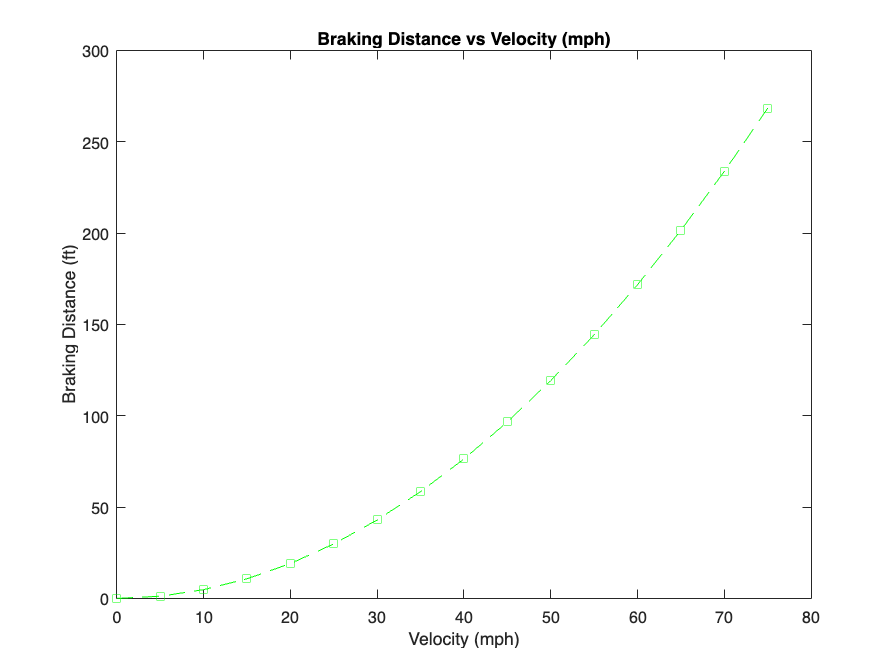

figure
plot(V, acceleration, '--gs')
xlabel('Velocity (mph)')
ylabel('Acceleration (g''s)')
title('Max Potential Deceleration (g''s) Due to Downforce vs Velocity (mph)')

## Braking Work ( not done/correcrt )

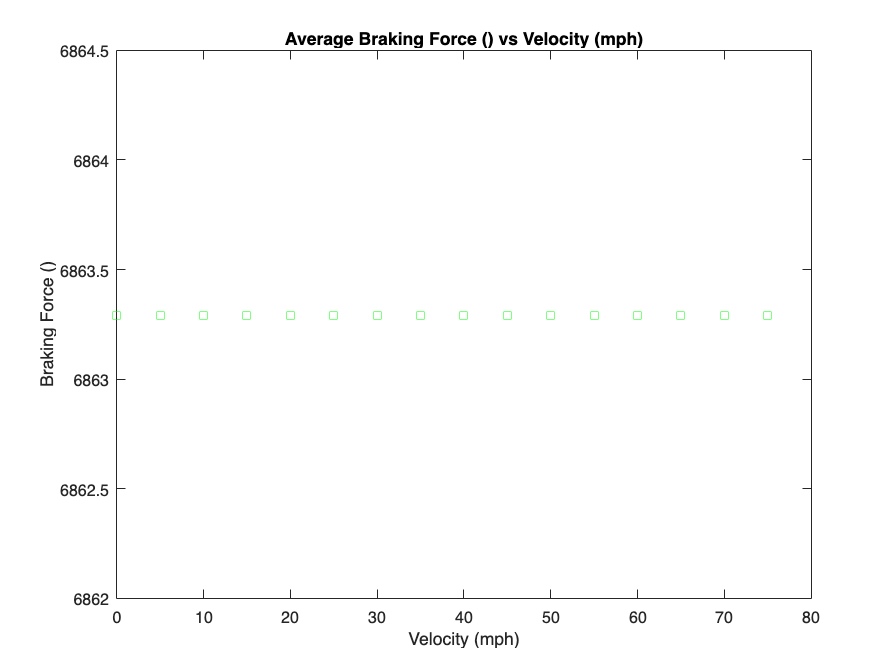

% work = f*s
% work = kinetic energy 
KE = (1/2)*W_total*V.^2;
braking_force = KE/braking_dist;

figure
plot(V, braking_force, '--gs')
xlabel('Velocity (mph)')
ylabel('Braking Force ()')
title('Average Braking Force () vs Velocity (mph)')